Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# TE-mode in rectangular waveguide (Section 6.2)

Volker Ziemann, 211111, CC-BY-SA-4.0

**Important:** this example requires the PDE toolbox!

Here we calculate the modes in a transverse-electric, or TE, waveguide. The geometry of this `waveguide` is particularly simple; it is just a rectangular box that is 10 cm wide and 5 cm high, defined as a polygon. We simply follow the same steps discussed in detail in the example with the C-shaped dipole magnet, also available from this web page.

clear all; close all;
waveguide=[2; 4;   0; 0.1; 0.1; 0;  0.05; 0.05; 0; 0];
gd=[waveguide];         % assemble geometry
ns=char('waveguide')';  % names of the regions                 
sf='waveguide'; 
g=decsg(gd,sf,ns);

In the next step we create the` model` and add the geometry `g` to it. After plotting the geometry and inspecting the names of the edges and the faces, we apply boundary conditions. Here we choose von-Neumann conditions, because the tangential component of the electric fields, which are the derivatives of the longitudinal magnetic field $H_z$, must vanish on the metallic surfaces. Since we will solve Equation 6.2 we can chose c=1 when specifying the material properties.

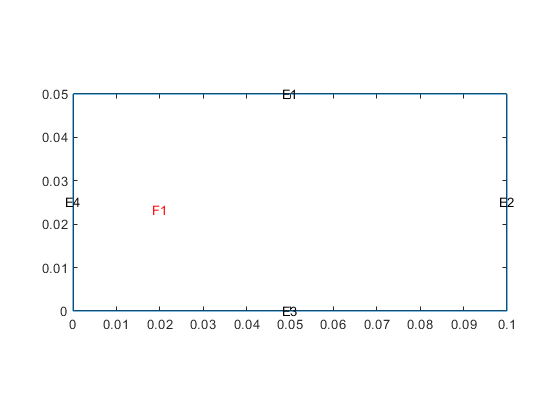

model=createpde(1);
geometryFromEdges(model,g);
pdegplot(model,'EdgeLabels','on','SubDomainLabels','on'); axis equal

applyBoundaryCondition(model,'Edge',[1:4],'q',0,'g',0); % von Neumann
specifyCoefficients(model,'m',0,'d',1,'c',1,'a',0,'f',0,'Face',1);

And now we mesh the geometry with a mesh size of 2 mm.

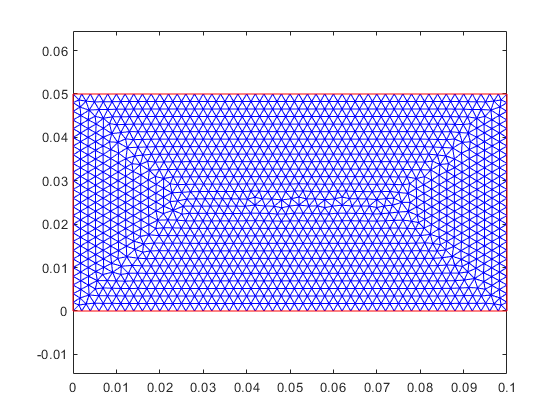

generateMesh(model,'Hmax',0.002); 
figure; pdemesh(model); axis equal;

Equation 6.2 is an eigenvalue equation and we therefore use `solvepdeeig(), `which returns the structure` result, `containing the eigenvalues and eigenvectors, to solve it. The second argument is the range in which the eigenvalues $k_z^2-\omega^2/c^2$ should be calculated. Then we give eigenvalues a name and call the eigenvectors  `Hz`  and 

result=solvepdeeig(model,[1,5000]); 

              Basis= 10,  Time=   0.14,  New conv eig=  0
              Basis= 11,  Time=   0.17,  New conv eig=  0
              Basis= 12,  Time=   0.18,  New conv eig=  0
              Basis= 13,  Time=   0.19,  New conv eig=  1
              Basis= 14,  Time=   0.20,  New conv eig=  1
              Basis= 15,  Time=   0.20,  New conv eig=  1
              Basis= 16,  Time=   0.21,  New conv eig=  1
              Basis= 17,  Time=   0.21,  New conv eig=  2
              Basis= 18,  Time=   0.21,  New conv eig=  2
              Basis= 19,  Time=   0.23,  New conv eig=  2
              Basis= 20,  Time=   0.23,  New conv eig=  3
              Basis= 21,  Time=   0.23,  New conv eig=  3
              Basis= 22,  Time=   0.24,  New conv eig=  5
End of sweep: Basis= 22,  Time=   0.24,  New conv eig=  5
              Basis= 15,  Time=   0.29,  New conv eig=  0
              Basis= 16,  Time=   0.29,  New conv eig=  0
End of sweep: Basis= 16,  Time=   0.30,  New conv eig=  0


eigenvalues=result.Eigenvalues; 
Hz=result.Eigenvectors;
disp([num2str(size(Hz,2)),' Eigenvalues found'])

4 Eigenvalues found


In order to evaluate the gradients, MATLAB requires information on the points `p`, the edges `e`, and triangles` t`, which is provided by the function `meshToPet()`. Once we have this information, we plot `mode=1` of Hz with pdesurf(). 

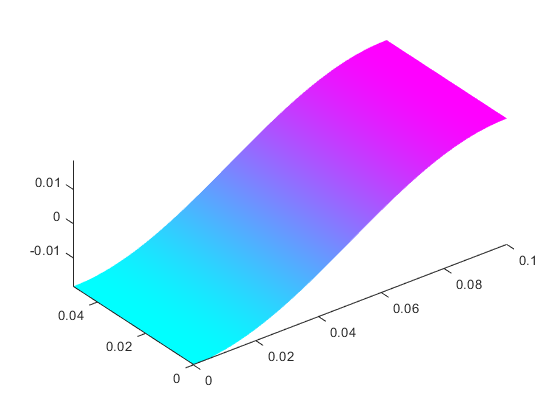

[p,e,t]=meshToPet(model.Mesh);
mode=1;     % select the mode to display
figure; pdesurf(p,t,Hz(:,mode)); axis equal;

Since the transverse fields are the derivatives of `Hz` we use `pdegrad()`to give us these and use Equation 6.1 to convert them to the magnetic fields `Hx` and `Hy,` as well as the electric fields `Ex` and `Ey`. In the upper figure we finally plot the electric and in the lower figure the magnetic field as a arrows. 

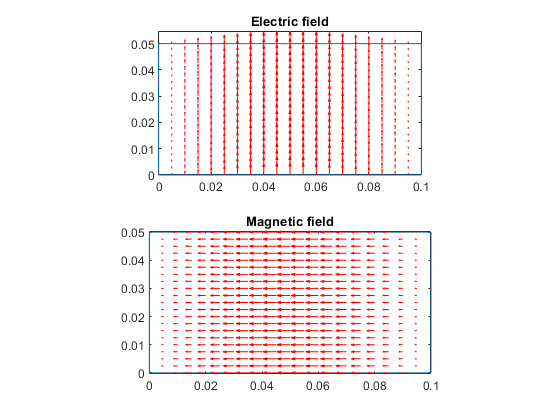

[Hx,Hy]=pdegrad(p,t,Hz(:,mode)); Hx=-Hx; Hy=-Hy; Ex=Hy; Ey=-Hx;
 figure;
subplot(2,1,1); pdegplot(model); hold on; pdeplot(model,'flowdata',[Ex;Ey]); 
axis equal; title('Electric field');
subplot(2,1,2); pdegplot(model); hold on; pdeplot(model,'flowdata',[Hx;Hy]); 
axis equal; title('Magnetic field');

Now you can check the size of eigenvalues and plot the all. Then you can increase the range in which eigenvalues are calculated and check out even higher ones.